# Script 9: Unit Commitment

Now that we can generate a forecast for future electricity demand, the next question is what actions should we take based on that forecast? One area of interest is how to operate a combination of power plants such that we meet our electrical needs while minimizing the cost of meeting those needs. This is commonly called a unit commitment problem. In this script, we will examine how to operate a combination of power plants to efficiently meet the needs of a week ahead forecast.

Based on work by Szilard Nement, [`szilard.nemeth@gamax.hu`](mailto:szilard.nemeth@gamax.hu)

## Power Plant Settings

In this example we will use a combination of four different power plants: an old coal plant, a new coal plant, a natural gas plant, and a peaker. You can see their relative costs and constraints in the table below.

load("unitCommData.mat");
disp(Plants)

                               CoalOld    CoalNew    Gas    Peaker
                               _______    _______    ___    ______
    FuelCost ($/MWh)              30         25       45       60 
    OperatingCost ($/h)           20         30       50       10 
    StartupCost ($/switch)       800        650      200       80 
    MinGenerationLevel (MW)      120         90       40        3 
    MaxGenerationLevel (MW)      800        250      200      120 
    RampUpLimit (MW/h)            30         40       80      900 
    RampDownLimit (MW/h)          50         50      100     1800 
    MinimumUpTime (h)              4          3        5        1 
    MinimumDownTime (h)            3     

Create a few variables for time throughout the week

numhours = numel(loadforecast);
time = (1:numhours)';

## Load Forecast vs Installed Capacity

We must first check that the load forecast is less than the total installed capacity of our power plants. If we cannot meet the forecast by running all our plants at 100% capacity, then we will be unable to meet the demands no matter how we operate the plants. In that case we will have to acquire more electricity from another source such as an adjacent grid, which is a very expensive option.  We may also choose to target a generation level slightly higher than our forecast to protect against variability in the system and inaccuracies in our model.

% add a buffer to the forecast
GenerationTarget = loadforecast * 1.05;
% check the total installed capacity of our plants
InstalledCapacity = sum(Plants{'MaxGenerationLevel (MW)',:});
% if our installed capacity cannot meet demand, generate an error
assert(InstalledCapacity > max(GenerationTarget), ...
    'Error! Maximum of load profile (%4.2f MW) is above installed capacity (%4.2f MW)!',...
    max(GenerationTarget), InstalledCapacity);

## Visualize load profile

Let's take a look at what the forecasted demand looks like for the next week.

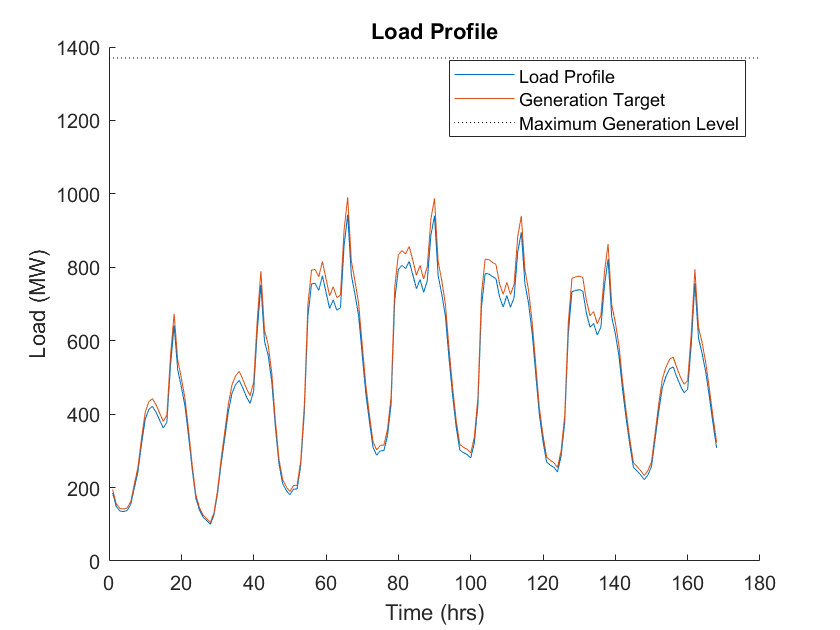

figure
hold on
plot(time,loadforecast)
plot(time,GenerationTarget)
plot(xlim,[InstalledCapacity InstalledCapacity], 'k:')
hold off
title('Load Profile')
ylabel('Load (MW)')
xlabel('Time (hrs)')
legend('Load Profile','Generation Target','Maximum Generation Level',...
    'Location','best')

## Optimization problem: variables, objective function, constraints

The Unit Commitment problem is typically solved using an optimization technique called mixed-integer linear programming.  This optimization technique requires the objective function and constraints to be a linear function of the decision variables, which enables us to solve problems with 1000’s of variables or more. “Mixed-integer” refers to the fact that variables can take on either continuous or discrete (integer) values.  Mixed-integer linear programming problems are solved using the INTLINPROG solver from Optimization Toolbox.

Before we can find the optimal solution, we must first figure out how to formulate the various costs and constraints in the system. This is a manual process that can be challenging in some problems. 

In this problem we track three different variables for each plant at each hour in order to determine the cost of our solution. These variables are how much electricity the plant is generating (fuel cost), whether the plant is on (operating cost), and whether the plant started up in that hour (startup cost). Keeping track of three variables for each plant at each hour gives us `4 plants * 168 hours * 3 variables/plant/hour = 2016 variables` that contribute to the cost and need to be simultaneously optimized. 

There are also a number of constraints placed upon how these variables can change, such as how quickly each plant can ramp up production once it is on (see the table at the beginning of the script). Our formulation has a total of 4860 constraints across our 2016 variables.

Each variable also has bounds on the range it can take. One of the variables we track each hour (amount of electricity generated) is a floating point number that can take any value between the plant's minimum and maximum generation levels, or can be zero when the plant is off. However the other two variables, whether the plant is on and whether it started up, are binary and can only be the integer values 0 or 1. 

## Setup the data for the problem

% pull apart plant properties
FuelCost            = Plants{1,:};
StartupCost         = Plants{2,:};
OperatingCost       = Plants{3,:};
MinGenerationLevel  = Plants{4,:};
MaxGenerationLevel  = Plants{5,:};
RampUp              = Plants{6,:};
RampDown            = Plants{7,:};
MinimumUpTime       = Plants{8,:};
MinimumDownTime     = Plants{9,:};

numplants = width(Plants);
plants = Plants.Properties.VariableNames;
idxHr2ToEnd=2:numhours;

## Define the optimization problem and the optimization variables

GeneratorSchedule = optimproblem;

maxGenConst = repmat(MaxGenerationLevel,numhours,1);
% amount of power generated in an hour by a plant
power = optimvar('power',numhours,plants,'LowerBound',0,'UpperBound',maxGenConst);
% indicator if plant is operating during an hour 
isOn = optimvar('isOn',numhours,plants,'Type','integer','LowerBound',0,'UpperBound',1);
% indicator if plant is starting up during an hour
startup = optimvar('startup',numhours,plants,'Type','integer','LowerBound',0,'UpperBound',1);

## Define the objective function

% costs
powerCost = sum(power*FuelCost',1);
isOnCost = sum(isOn*OperatingCost',1);
startupCost = sum(startup*StartupCost',1);

% set objective
GeneratorSchedule.Objective = powerCost + isOnCost + startupCost;

## Demand constraints

Power generation over all plans meets hourly demand

GeneratorSchedule.Constraints.isDemandMet = sum(power,2) >= GenerationTarget;

## Constraints linking plant operating status to power generation

Only gen power when plant is on if isOn=0 power must be zero, if isOn=1 power must be less than maxGenConst.

GeneratorSchedule.Constraints.powerOnlyWhenOn = power <= maxGenConst.*isOn; 

% if on, meet MinGenerationLevel
minGenConst = repmat(MinGenerationLevel,numhours,1);
GeneratorSchedule.Constraints.meetMinGenLevel = power >= minGenConst.*isOn; % if isOn=0 power >= 0, if isOn=1 power must be more than minGenConst

## Constraints linking operating status change to startup

Enforce startup=1 when moving from off to on.  There's no need to enforce startup=0 at other times since minimizing cost forces it.

GeneratorSchedule.Constraints.startupConst = -isOn(idxHr2ToEnd-1,:) + isOn(idxHr2ToEnd,:) - startup(idxHr2ToEnd,:) <= 0;

## Ramprate limit constraints

The generation level cannot increase or decrease in one hour by more than its rampup/rampdown limit, except when it is turning on and off. When turning on it must be able to get from zero to its minimum generation level, even if that gap is larger than its ramp up limit. Likewise when turning off, it must be able to get form its minimum generation level down to zero, even if that gap is larger than its ramp down limit.

% rampup limit
RampUpConst = repmat(RampUp,numhours-1,1);
GeneratorSchedule.Constraints.rampupConst = -power(idxHr2ToEnd-1,:) + power(idxHr2ToEnd,:) <= RampUpConst(idxHr2ToEnd-1,:) + ...
     max(minGenConst(idxHr2ToEnd,:)-RampUpConst(idxHr2ToEnd-1,:),0).*startup(idxHr2ToEnd,:);
 
% rampdown limit
RampDownConst = repmat(RampDown,numhours-1,1);
GeneratorSchedule.Constraints.rampdownConst = power(idxHr2ToEnd-1,:) - power(idxHr2ToEnd,:) <= max(minGenConst(idxHr2ToEnd,:),RampDownConst(idxHr2ToEnd-1,:)) - ...
    max(minGenConst(idxHr2ToEnd,:)-RampDownConst(idxHr2ToEnd-1,:),0).*isOn(idxHr2ToEnd,:);

## Minimum uptime and downtime constraints

Once a plant turns on, it must stay on for a certain number of hours before it can be turned off again. Similarly, once off it must stay off for a certain number of hours before it can be turned on again.

% min uptime
GeneratorSchedule.Constraints.minUptimeConst = optimconstr(numhours,plants);
for jj = 1:numplants
    for kk = 1:numhours % based on possible startups; no penalty at end for running over
        idx = kk + (jj-1)*numhours;
        if kk > numhours-MinimumUpTime(jj)
            sumidx = idx:jj*numhours;
        else
            sumidx = idx:idx+MinimumUpTime(jj)-1;
        end
        GeneratorSchedule.Constraints.minUptimeConst(kk,jj) = ...
            startup(idx) - sum(isOn(sumidx)/length(sumidx)) <= 0;
    end
end

% min downtime
GeneratorSchedule.Constraints.minDowntimeConst = optimconstr(numhours,plants);
for jj = 1:numplants
    for kk = 2:numhours % based on possible startups; no penalty at end for running over
        idx = kk + (jj-1)*numhours;
        if kk <= MinimumDownTime(jj)
            sumidx = (jj-1)*numhours+1:idx-1;
        else
            sumidx = idx-MinimumDownTime:idx-1;
        end
        GeneratorSchedule.Constraints.minDowntimeConst(kk,jj) = ...
            startup(idx) + sum(isOn(sumidx)/length(sumidx)) <= 1;
    end
end

## Find the optimal generation schedule

Now that we have our optimization problem, we can find the optimal generation schedule for our plants to meet our electricity needs while minimizing costs. Since we have a mix of floating point variables and integer variables, this is called a mixed integer problem. We will use the `solve` function from Optimization Toolbox to solve this problem. That function will apply the `intlinprog` solver because the problem is a mixed integer problem. 

In the results, note that we acheive a relative gap, which is the difference in cost between the best solution we found and the theoretical best, of around 1%. Ideally we would like the gap to be zero, however as is often the case we can get a good solution quickly but finding the absolute best solution can take much longer. Whether these results represent good accuracy or performance is very dependent on the particular problem; however in this type of allocation of power plants, a 1% relative gap is a fairly good result.

% options for the optimization algorithm, here we set the max time it can run for
options = optimoptions('intlinprog', 'MaxTime', 45);
% call the optimization solver to find the best solution
[sol, totalcost, exitflag, output] = solve(GeneratorSchedule, 'Options', options);


Solving problem using intlinprog.
LP:                Optimal objective value is 2.703559e+06.                                         

Cut Generation:    Applied 63 Gomory cuts,                                                          
                   227 implication cuts, 246 clique cuts,                                           
                   348 cover cuts, 270 flow cover cuts,                                             
                   and 37 mir cuts.                                                                 
                   Lower bound is 2.777661e+06.                                                     

Cut Generation:    Applied 43 Gomory cuts,                                                          
                   10 implication cuts, 37 clique cuts,                                             
                   and 67 flow cover cuts.                                                          
                   Lower bound is 2.781505e+06.       

## Reshape and Visualize Optimized Schedule Data

Now we can plot the optimal schedule for the next week using a local function found at the bottom of this script. The plot shows for each of the four plants, at each hour of the week, how much electricity it should be generating. If the cell is blank, then the plant is off. Otherwise its color represents how much it should be generating between its minimum and maximum capacity. We can see that all four plants will be cycled on and off multiple times throughout the week.

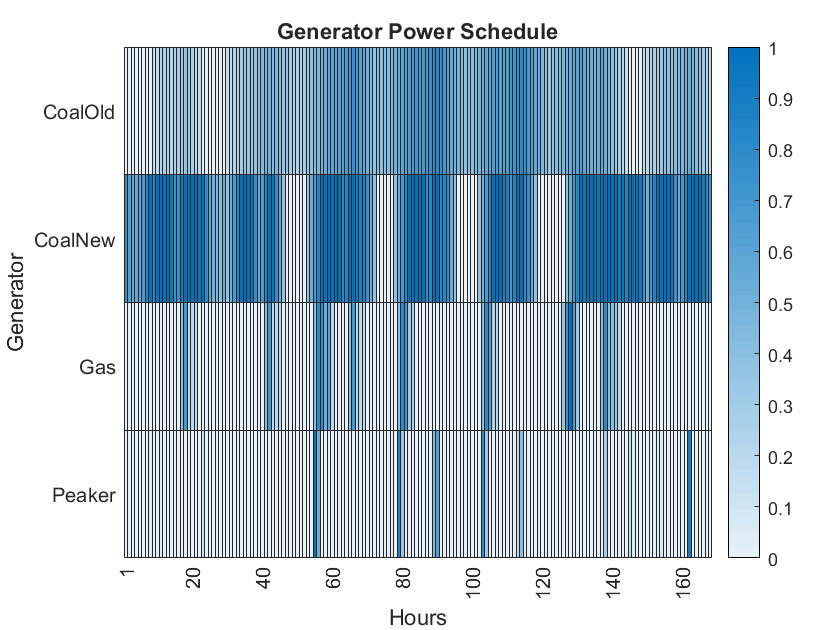

Schedule = sol.power;
OperationFraction = Schedule ./ Plants{'MaxGenerationLevel (MW)', :};
h = heatmap(OperationFraction.', "YData", Plants.Properties.VariableNames);
h.XDisplayLabels(~ismember(1:168,[1 20:20:160])) = {''};
xlabel("Hours")
ylabel("Generator")
title("Generator Power Schedule")

## Compare Scheduled Generation with Generation Target

Finally, let's compare what we wanted to generate vs what we have actually scheduled to generate based on the optimization solver. Note that in most places, the scheduled generation follows the generation target so closely that you can't see any difference. However in some places the scheduled generation is higher than the target, and we generate a surplus. This overproduction is due to the rampup and rampdown constraints forcing the solver to overproduce in order to ensure that  the demand is met or exceeded at all points.

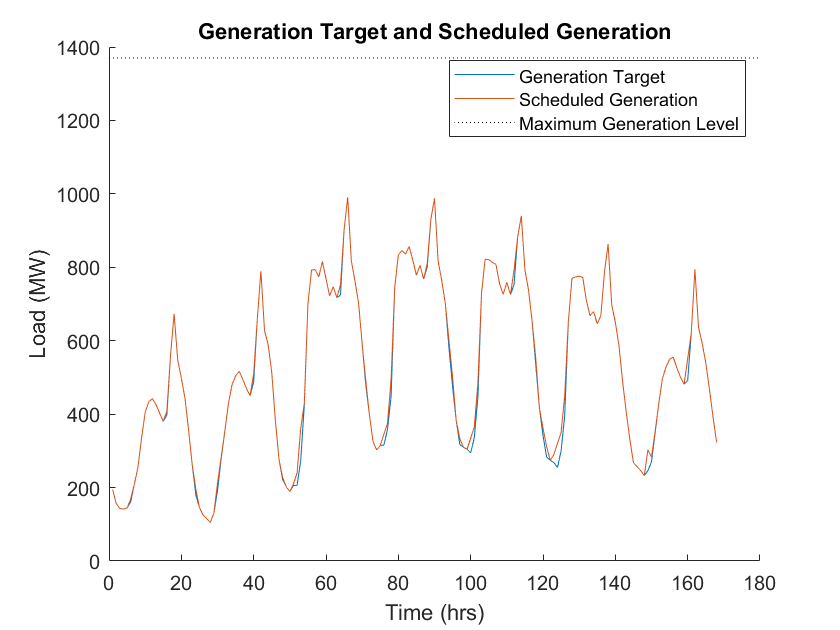

figure
hold on
plot(time,GenerationTarget)
plot(time,sum(Schedule,2))
plot(xlim,[InstalledCapacity InstalledCapacity], 'k:')
hold off
title('Generation Target and Scheduled Generation')
ylabel('Load (MW)');
xlabel('Time (hrs)');
legend('Generation Target','Scheduled Generation','Maximum Generation Level',...
    'Location','best');